% Task 3
clear all;close all;
A = [5 -3;0 4];
Asvd = 1/sqrt(5)*[1 -2;2 1]*[sqrt(10) 0;0 sqrt(40)]*[1 1;-1 1]*1/sqrt(2);
u1 = A*[1;1]*1/sqrt(2)*1/sqrt(10);
u1*1*sqrt(5);
Vtx = [1 1;-1 1]*1/sqrt(2)*[1;1];

% figure
% axis([-1.5 1.5 0 1.5])
% grid on
% 
% annotation('textarrow',[0.5133 0.7746],[0.1136 0.649],"LineWidth",4)
% figure
% axis([-1.5 1.5 0 1.5])
% grid on
% 
% annotation('arrow',[0.5161 0.875],[0.1143 0.1095],"LineWidth",4)
% sVtx = sym([sqrt(10) 0;0 sqrt(40)]*[1 1;-1 1]*1/sqrt(2)*[1;1])
% figure
% axis([-4.5 4.5 0 4])
% grid on
% annotation('arrow',[0.5143 0.9036],[0.1143 0.1119],"LineWidth",4)
% UsVtx = sym(1/sqrt(5)*[1 -2;2 1]*[sqrt(10) 0;0 sqrt(40)]*[1 1;-1 1]*1/sqrt(2)*[1;1]);
% figure
% axis([-4.5 4.5 0 4])
% grid on
% annotation('arrow',[0.5161 0.6857],[0.1143 0.9238],"LineWidth",4)
[V,D]=eig(A);
Xinvx = [0 1;1 -3]*[1;1];
LXinvx = [4 0;0 5]*Xinvx;
xsx = [3 1;1 0]*LXinvx;

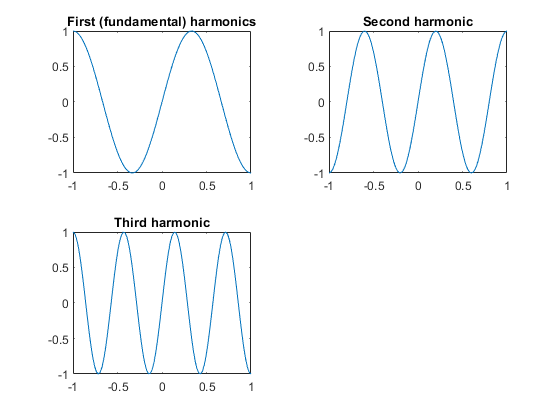

% Task 1

x = linspace(-1,1);
h1 = sin(3*pi/2*x);
h2 = sin(5*pi/2*x);
h3 = sin(7*pi/2*x);
figure
tiledlayout(1,3);
title("")
nexttile
plot(x,h1)
title("First (fundamental) harmonics")
nexttile
plot(x,h2)
title("Second harmonic")
nexttile
plot(x,h3)
title("Third harmonic")

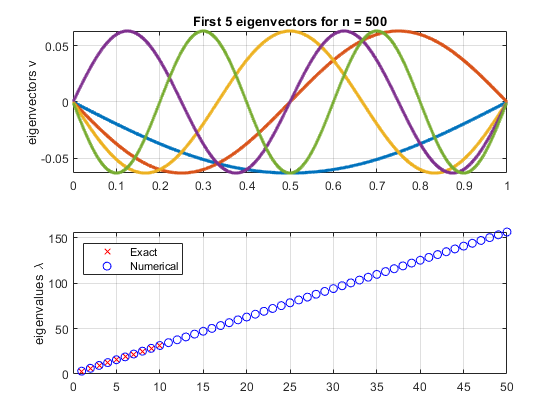

% task2
clear all; close all;

L =1 ;
n = 500;
epsilon = 0;
h = L/(n+1);
x = h*(1:n)';


A = 1/h^2*toeplitz([2 -1 zeros(1,n-2)]);
K = diag(1-epsilon.*x.*(1-x));
B = inv(K)*A;
[V,D] = eig(B);
% analytical solution
exactEvalues = (1:n)'*pi;
exactEvectors = diag(sin(x*pi));
numeric= sqrt(diag(D));


figure
tiledlayout(2,1)
nexttile
plot(x,V(:,1:5),'.-');grid on;ylabel('eigenvectors v',"Interpreter","tex"   )
title("First 5 eigenvectors for n = 500")
nexttile
plot(exactEvalues(1:10),'rx'),ylabel('eigenvalues \lambda',"Interpreter","tex")
hold on 
plot(numeric(1:50),'bo')
hold off;grid on;
legend("Exact","Numerical",'Location','NW')

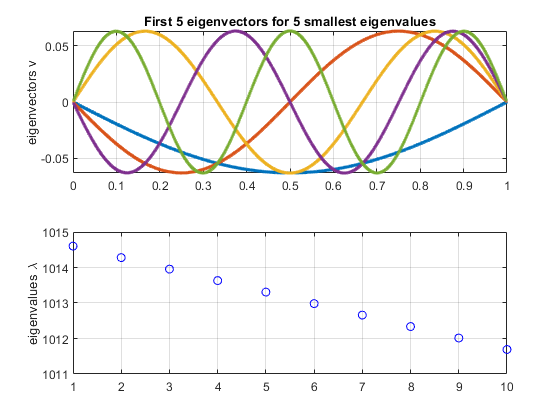

epsilon = 0.1;
A = 1/h^2*toeplitz([2 -1 zeros(1,n-2)]);
K = diag(1-epsilon.*x.*(1-x));
B = inv(K)*A;
[V,D] = eig(B);
numeric= sqrt(diag(D));
[evectors,eval]= find5vectors(V,numeric);
figure
tiledlayout(2,1)
nexttile
plot(x,evectors,'.-');grid on;ylabel('eigenvectors v',"Interpreter","tex"   )
title("First 5 eigenvectors for 5 smallest eigenvalues")
nexttile
plot(numeric(1:10),'bo'),ylabel('eigenvalues \lambda',"Interpreter","tex");grid on

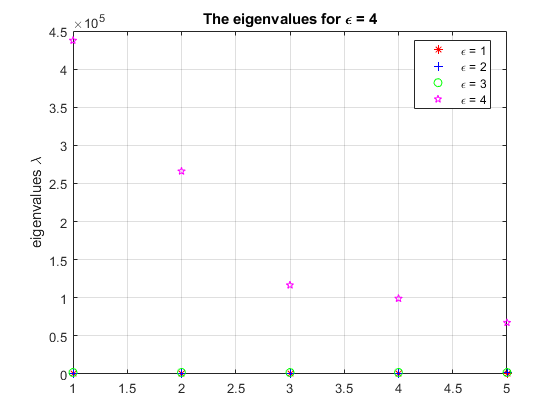


    epsilon = 1;
    A = 1/h^2*toeplitz([2 -1 zeros(1,n-2)]);
    K = diag(1-epsilon.*x.*(1-x));
    B = inv(K)*A;
    [V,D] = eig(B);
    numeric= sqrt(diag(D));
    figure
    plot(numeric(1:5),'r*'),ylabel('eigenvalues \lambda',"Interpreter","tex");grid on;hold on

    epsilon = 2;
    A = 1/h^2*toeplitz([2 -1 zeros(1,n-2)]);
    K = diag(1-epsilon.*x.*(1-x));
    B = inv(K)*A;
    [V,D] = eig(B);
    numeric= sqrt(diag(D));
    plot(numeric(1:5),'b+'),ylabel('eigenvalues \lambda',"Interpreter","tex");grid on;
   
    epsilon = 3;
    A = 1/h^2*toeplitz([2 -1 zeros(1,n-2)]);
    K = diag(1-epsilon.*x.*(1-x));
    B = inv(K)*A;
    [V,D] = eig(B);
    numeric= sqrt(diag(D));
    plot(numeric(1:5),'go'),ylabel('eigenvalues \lambda',"Interpreter","tex");grid on;
    
 
    epsilon = 4;
    A = 1/h^2*toeplitz([2 -1 zeros(1,n-2)]);
    K = diag(1-epsilon.*x.*(1-x));
    B = inv(K)*A;
    [V,D] = eig(B);
    numeric= sqrt(diag(D));
    plot(numeric(1:5),'mp'),ylabel('eigenvalues \lambda',"Interpreter","tex");grid on;
    title("The eigenvalues for \epsilon = 4","Interpreter","tex")
    legend("\epsilon = 1","\epsilon = 2","\epsilon = 3","\epsilon = 4","Interpreter","tex","Location","best")

function [evectors,evalues] = find5vectors(V,Dvector)
    evectors = zeros(size(V,1),5);
    evalues = zeros(1,5);
    for i = 1:5
        [val,idx] = min(Dvector);
        evalues(i)=val;
        evectors(:,i) = V(:,idx);
        Dvector(idx)=1e6;
    end
end